## Clear Workspace

clc
clearvars
close all

unit = 10^(-3);             %all units in mm

## Variables for the conical Antenna

D = (20*unit)/2;               %Radius of the waveguide
dm = (108.7*unit)/2;               %Radius of the cone aperture
Lhorn = 92.2*unit;               %Length of the cone attachment
Lwg = 1.4*22.2*unit;                  %Length of the waveguide x2 f zu niedirig, x1 f zu groß, 1.4x gut
Lprobe = 7.15*unit;              %height of the Probe inside the waveguide
Fw = 0.2*unit;              %width of the Probe inside the waveguide
LBoden = 1.6*7.4*unit;             %Distance beetween bottomend of the waveguide an the probe 1.75 was ok, 1.9 besser, 1.5 zzu wenig
Material = metal("Aluminium")

Material =   metal with properties:

            Name: 'Aluminium'
    Conductivity: 37700000
       Thickness: 7.6200e-04

For more materials see catalog



freq = 10.489*10^(9);       %Frequency of interest

## Creation of the Antenna element

ant = hornConical(Radius=D, ...
    ApertureRadius=dm, ...
    WaveguideHeight=Lwg, ...
    ConeHeight=Lhorn, ...
    FeedHeight=Lprobe, ...
    FeedWidth=Fw, ...
    FeedOffset=LBoden, ...
    Conductor=Material)

ant =   hornConical with properties:

             Radius: 0.0100
    WaveguideHeight: 0.0311
         FeedHeight: 0.0072
          FeedWidth: 2.0000e-04
         FeedOffset: 0.0111
         ConeHeight: 0.0922
     ApertureRadius: 0.0544
          Conductor: [1×1 metal]
               Tilt: 0
           TiltAxis: [1 0 0]
               Load: [1×1 lumpedElement]


## Analysis of the Antenna

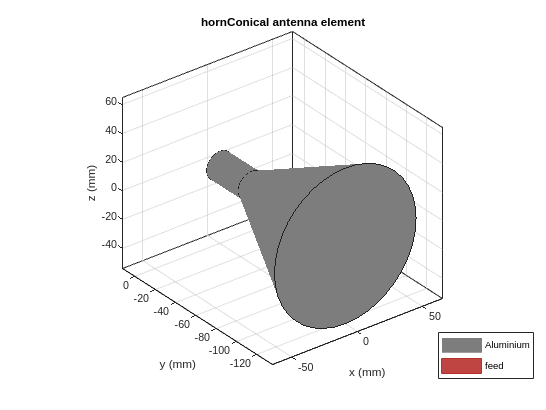

show(ant)           

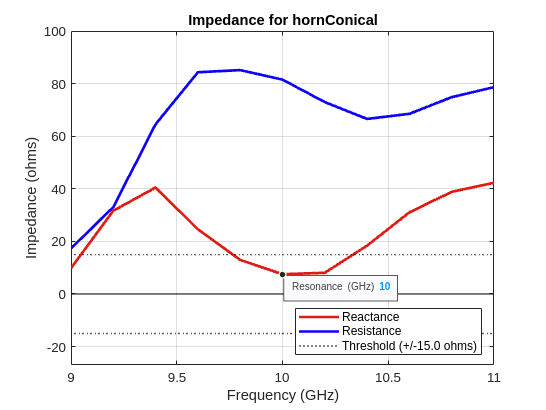

ans = 1.0000e+10

pattern(ant,freq)
resonantFrequency(ant,9e9:200e6:11e9)

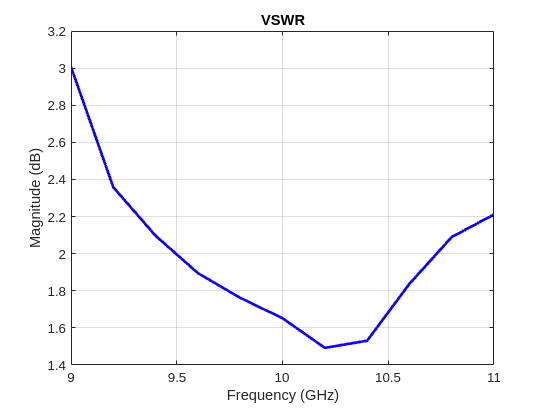

vswr(ant,9e9:200e6:11e9)

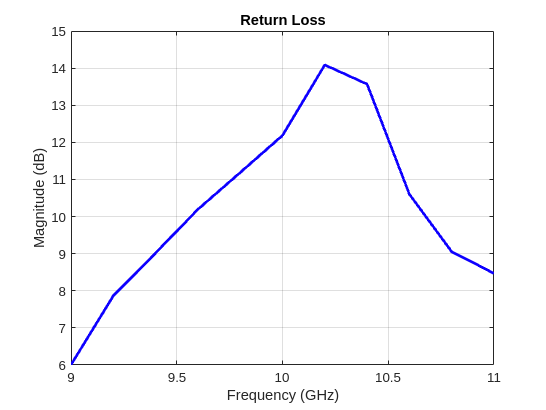

returnLoss(ant,9e9:200e6:11e9)